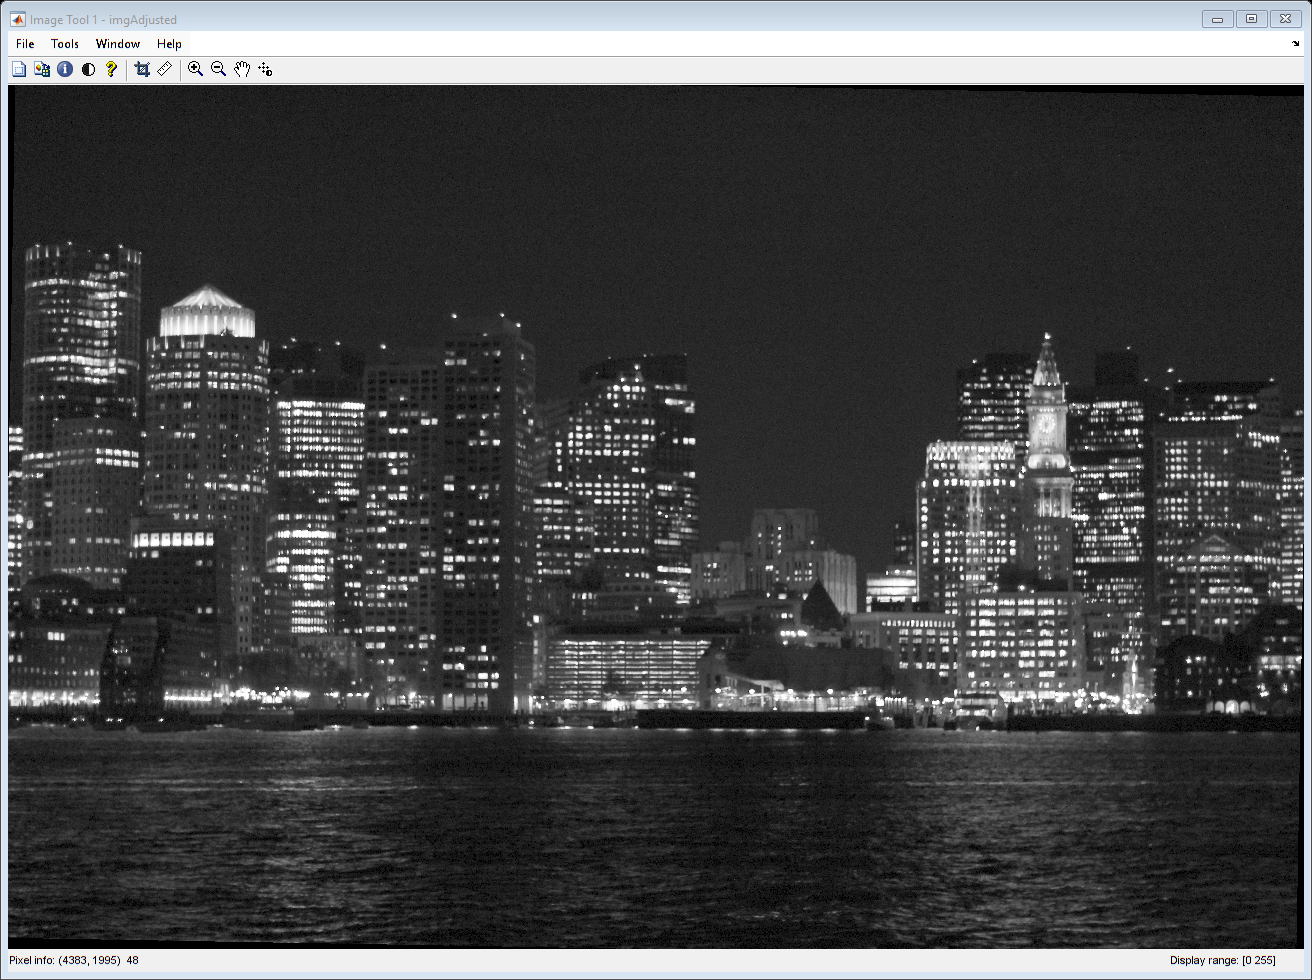

img = imread("boston night.JPG");
% Enter your code below

% Convert to grayscale
grayImg = rgb2gray(img);

% Rescale to [0,1]
imgDouble = im2double(grayImg);

% Gamma correction, gamma = 1/2
gamma = 1/2;
imgGamma = imgDouble .^ gamma;

% Rotate 1 degree CLOCKWISE (negative angle), keep same size
imgRotated = imrotate(imgGamma, -1, "crop");

% Convert back to uint8
imgAdjusted = im2uint8(imgRotated);


imtool(imgAdjusted)